**Lee and Shetzen cross correlation technique**

In this programm I will apply the cross correletion technique of Lee and Shetzen to examine the Wiener kernals of the system. After these are found the corresponding Volterra functionals will be determined.

**Loading the data**

load Jochem.mat %loading data file 

**Auto correlation property of the GWN data**

Firstly we need to check that the GWN data fullfills the auto-correlation property, the autocorrelation should be equal to the mean of the data squared, which will be 0 in the case of GWN data. The expectation value of the data should also equal 0 for odd, and 1 for even powers of the gwn signal.

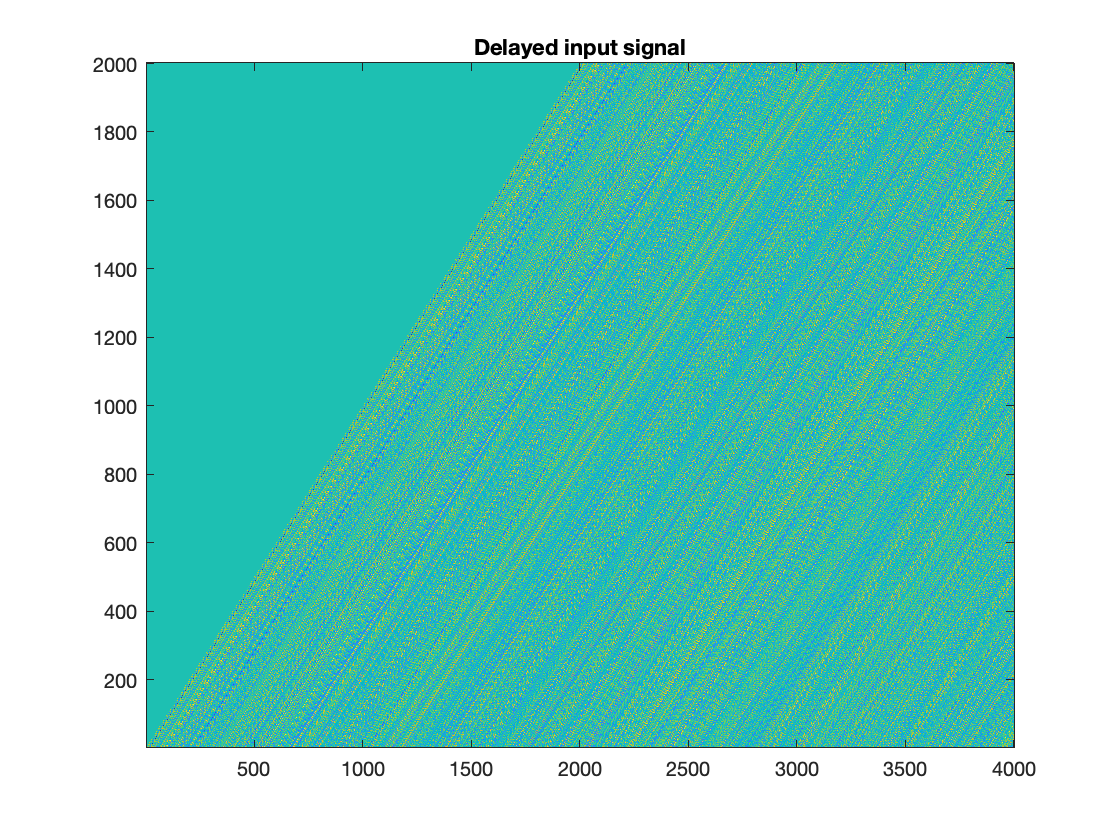

a_corr_gwn=phi_yx2(gwnt,gwnt,2000);

EGWN1=mean(gwnt) %indeed see that the mean of the gwn signal is about 0

EGWN1 = 0.0108

EGWN2=mean(gwnt.*gwnt) %and that the product has a mean of about 1

EGWN2 = 0.9971

disp(max(a_corr_gwn)); %the maximum result from the integral is small, so the

    0.0436



%gwn signal indeed has about a zero autocorrelation. Note that the result
%varries for different time differences, M, that are used. For M=0 I
%obtain 1, which is expected as these are identical (and the result should
%be a dirac delta which is 1 if the timing is the exact same). For large M
%(eg. M=2000), this results in ~0.04 (so very small). 

**Exploring the wiener function**

P = 0.4862

     1



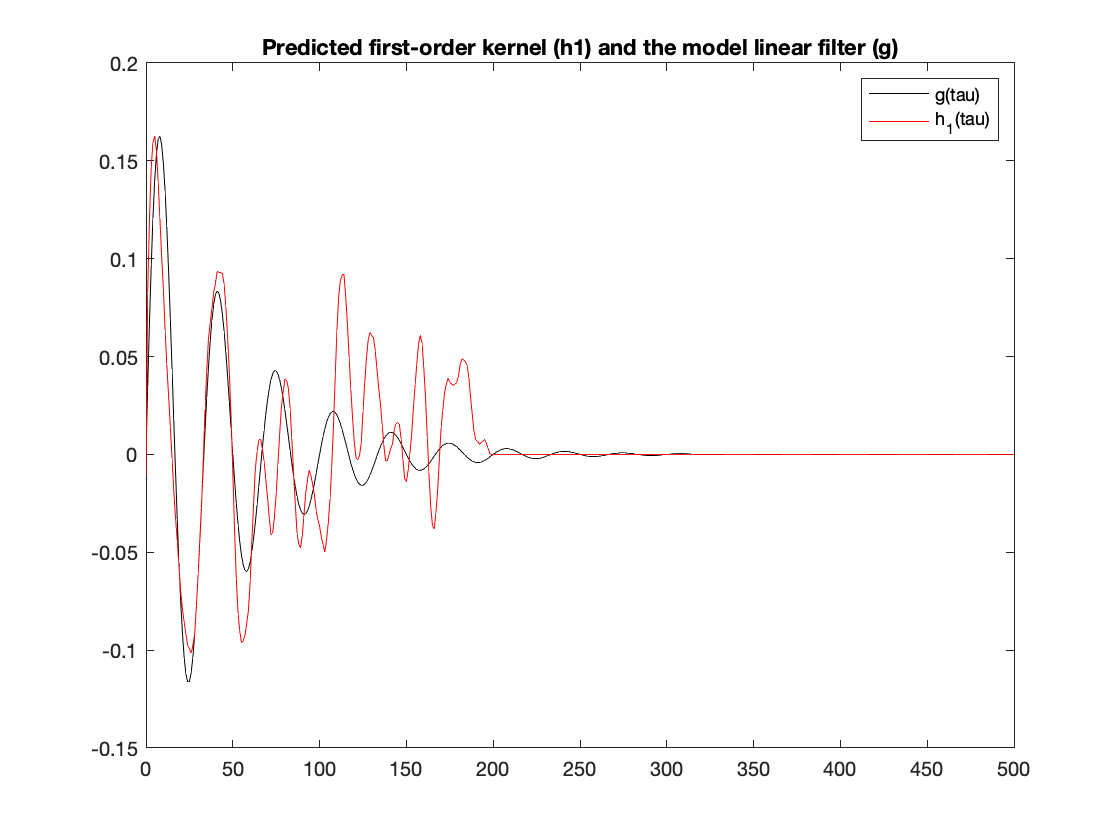

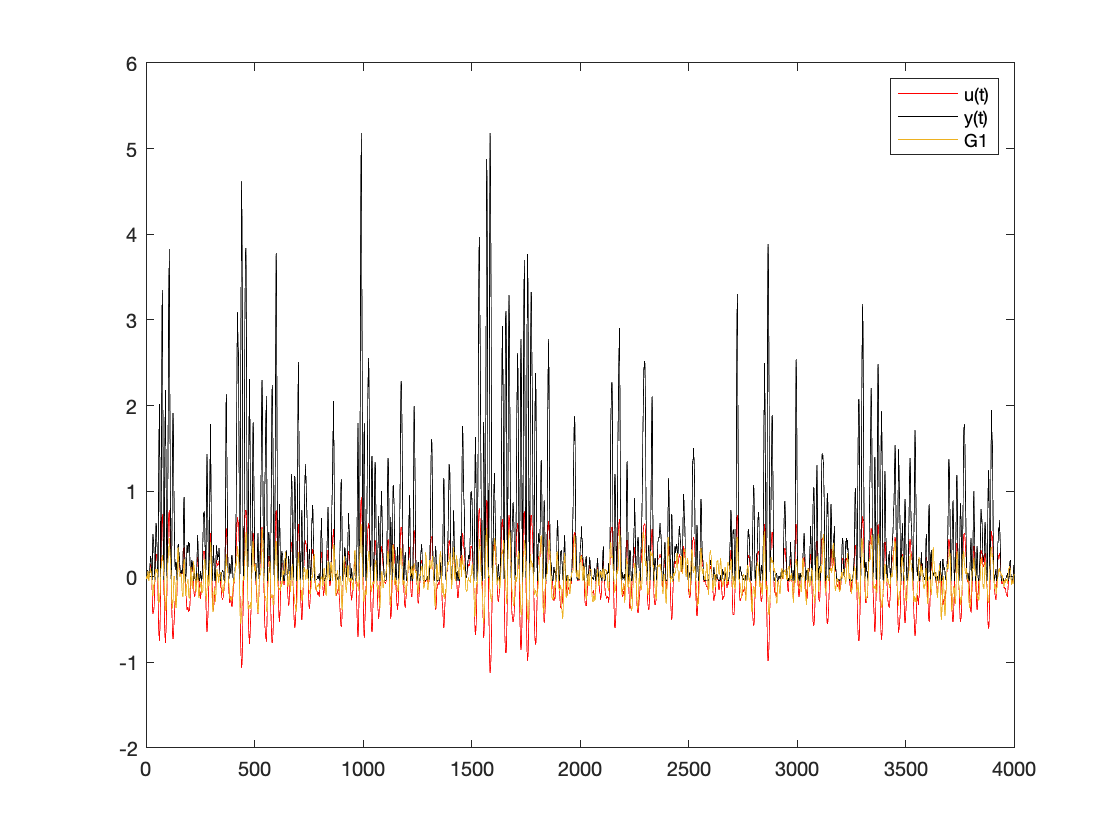

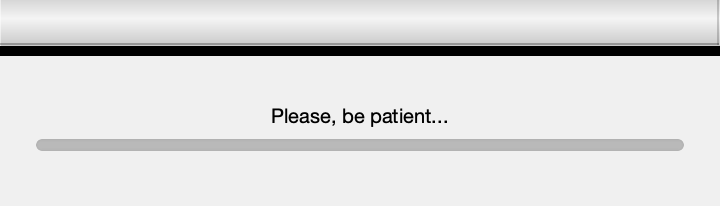

    1.0000



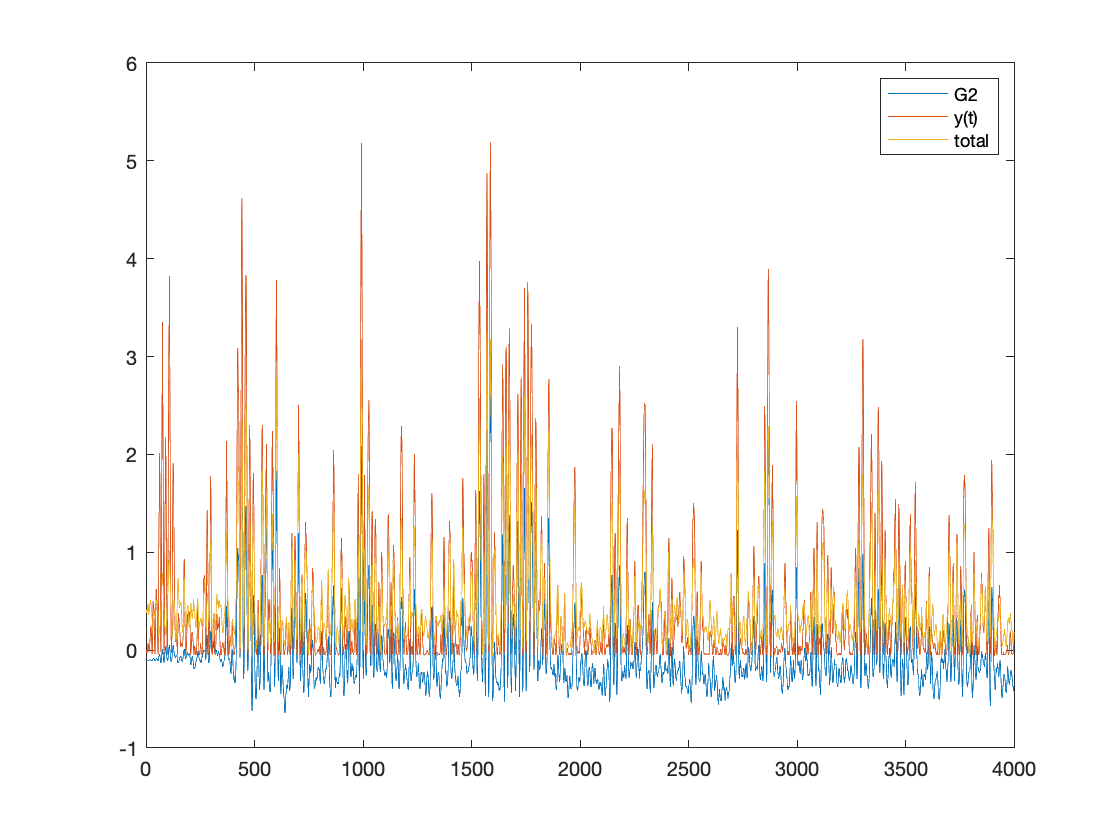

    1.0000    0.9454
    0.9454    1.0000

    1.0000    0.9184
    0.9184    1.0000

    1.0000    0.3273
    0.3273    1.0000



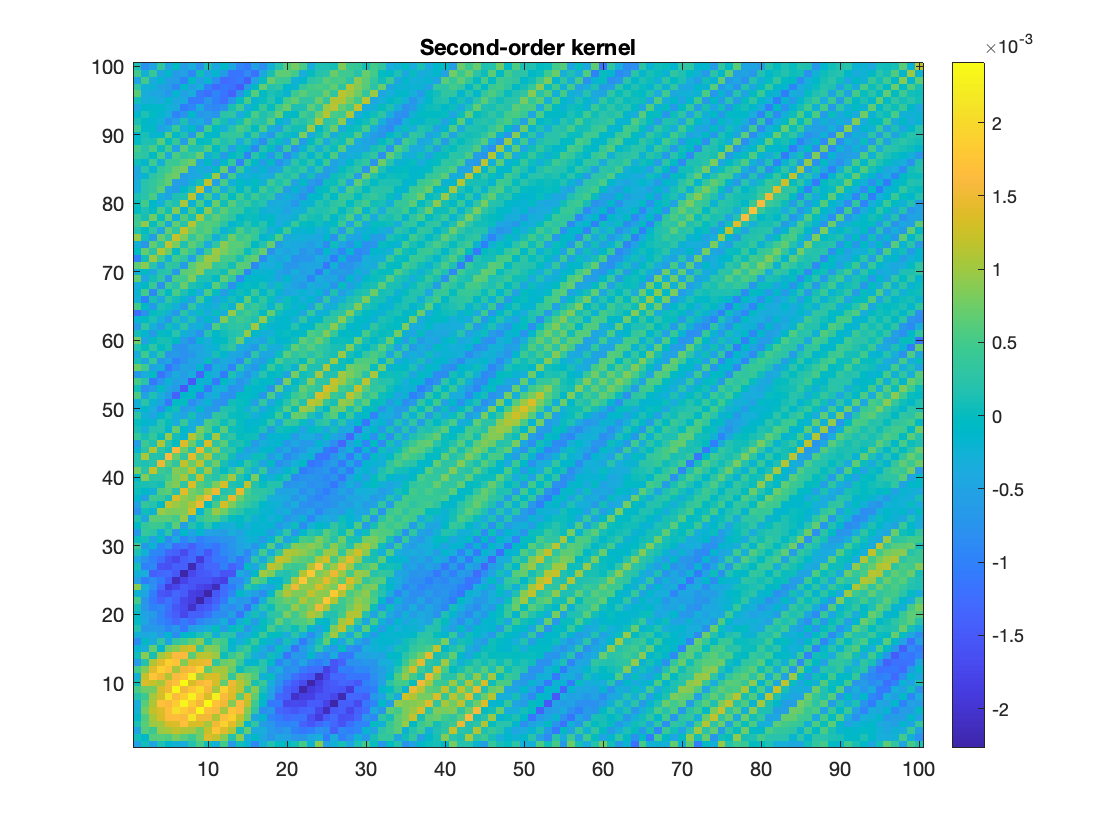

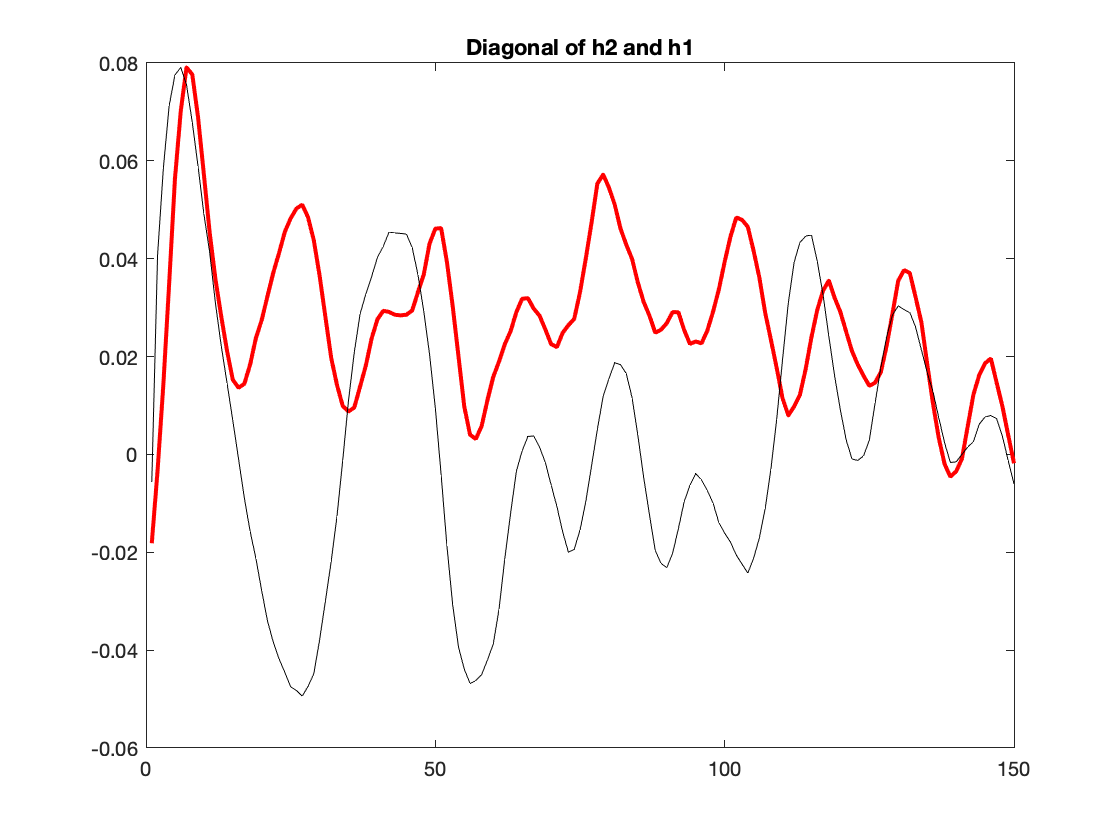

%[h0,h1,h2] = wiener(2,0); %(no nonlinearity)
%indeed see that h2 is not very informative for a system without
%nonlinearity
%[h0,h1,h2] = wiener(0,1); %(no linearity)
%indeed see that h1 does not perform well for a nonlinear system
[h0,h1,h2] = wiener(1,5); %we see that for higher b values the part that the G2 plays becomes larger, as is evident by the higher corrcoef values and something similar for a values and G1

**Now that we have played around with the wiener function for a while, and determined how the different parameters seem to work, we can try to work on the actual input files.**

clf('reset')
input=input1;
output=output1;
P = std(output) % the power of the input

P = 7.9295e-04

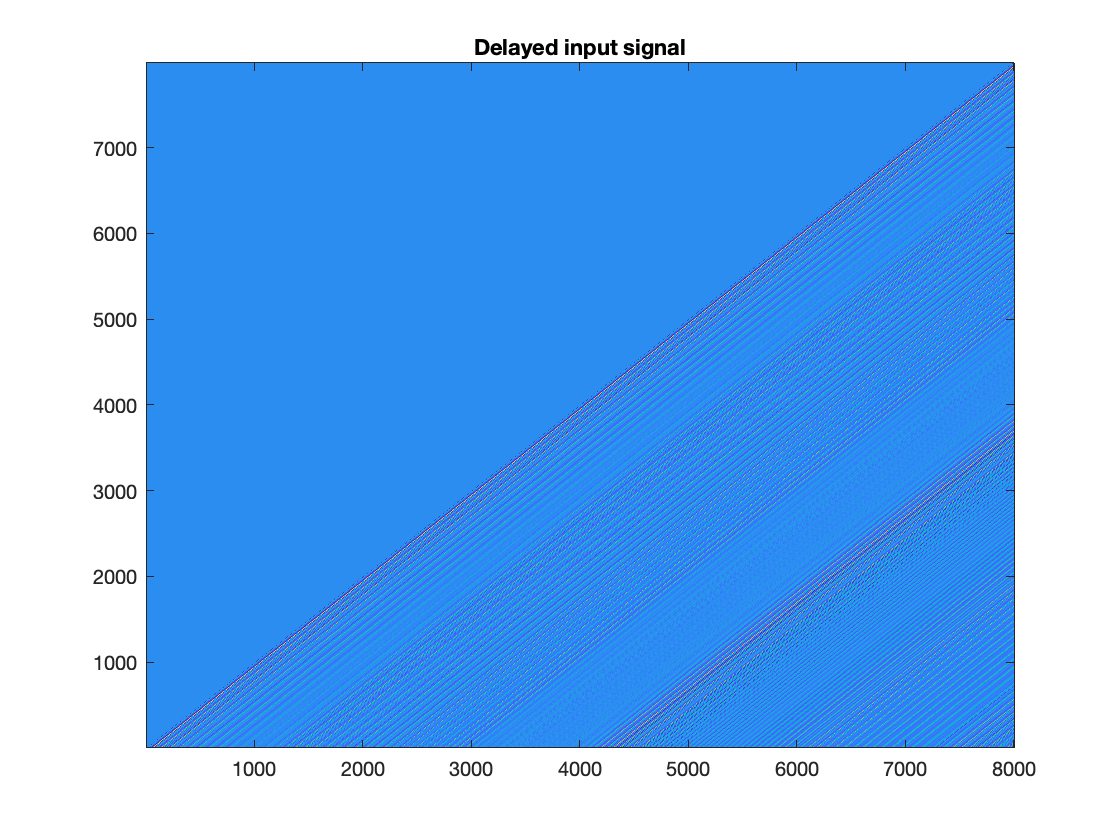


%the zeroth order as before
h0=mean(output);
G0 = h0;       % the zero-order Wiener prediction
y0 = output - G0;      % the Lee-Schetzen method: subtract h0 from the response

%  first order estimate: crosscorrelate
%
zero_range=200;
fi1 = phi_yx2(y0, input, length(input)-15);   %first-order kernel

h1=fi1/P;       % only positive tau! 
h1(zero_range:(8000-zero_range))=0; 

%the below was when comparing g1 with the input in the corrcoef
%I do see a increase in the corrcoef values when not taking into acount the
%data from around timestep 188 (the optimal value found for input1 was around 190)
%then for input 2 this also resulted in relatively gigh postive values, but
%then the input 3 turned out to be negative, but after a small search it
%was found that the value for 188 was potitive for all three

s=sum((h1)); %get a sum over h1 of one if we take away the absolute value, but get worse results
h1 = h1/s; % normalise the integral to one (this is a "tweaking point.." )
dt=1;
disp(sum(h1)*dt);

    1.0000



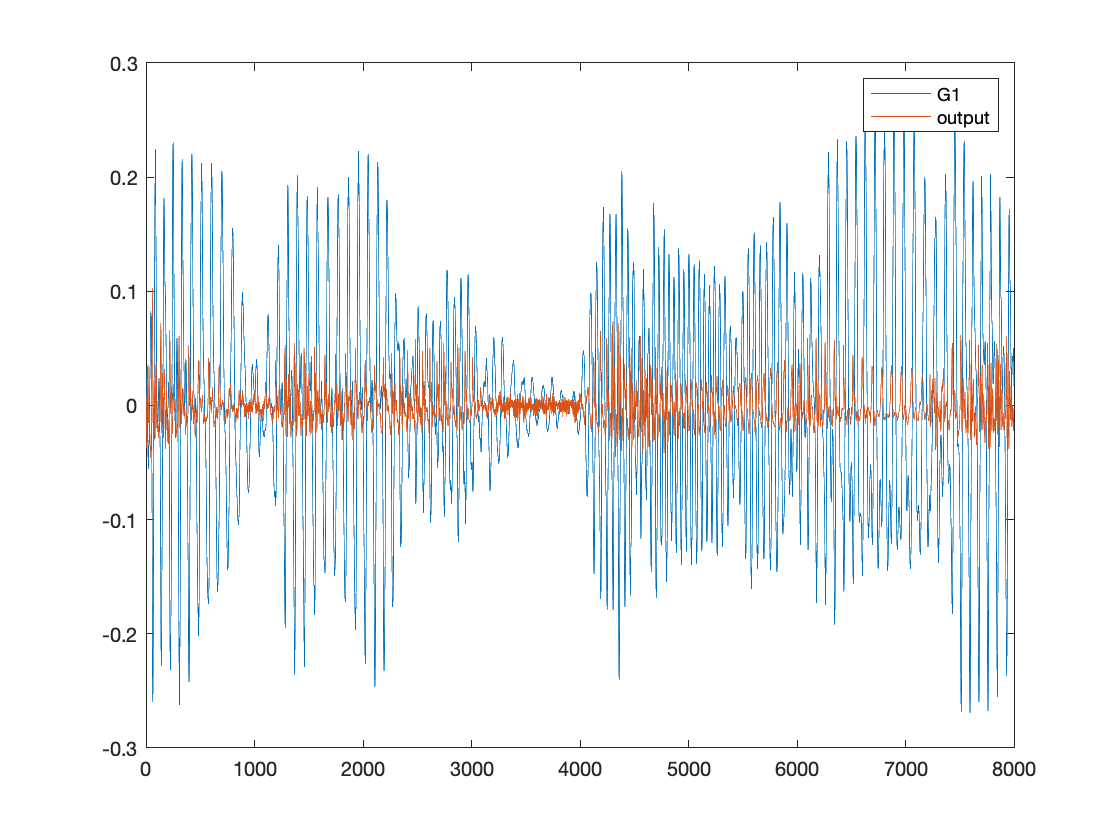


m1=max(h1);
m2=max(input);
m3=m1/m2;     

G1 = conv(input, h1);      % 1e order Wiener prediction with the scaled kernel 
G1 = G1(1:length(input));
figure(15)
plot(G1);  
hold on
plot(input);
hold off
legend('G1','output');

disp(corrcoef(G1/m3,output));

    1.0000    0.9448
    0.9448    1.0000



y1 = output - G0 - G1;

fi2=phi_yxx2(y1, input);              

h2=fi2/(2*P^2);         % the 2nd order Wiener kernel: only positive tau1, tau2 
s = sum(sum((h2)));  % total integral of the kernel
h2 = h2/s;              % normalize the kernel to one   
disp(sum(sum(h2))*dt);

    1.0000




G2 = convh2xx(h2,input,P);
disp(corrcoef(G0+G1+G2,output));

    1.0000    0.9458
    0.9458    1.0000

